Erlang

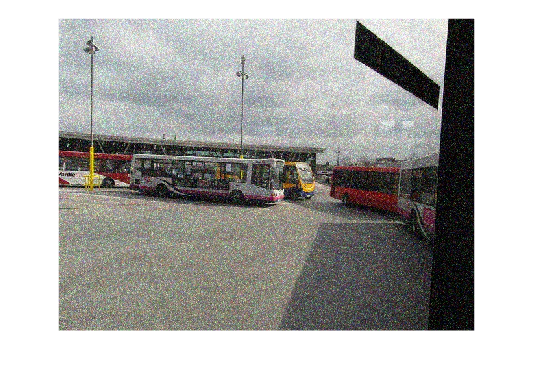

i = imageReader('erlang_rayl');
imshow(i);

[i2, niqe_noise, niqe_denoised] = noiseSelector(i, 'erlang_rayleigh')

i2 = 'iVBORw0KGgoAAAANSUhEUgAAAoAAAAHgCAIAAAC6s0uzAAAAB3RJTUUH6QcJCy4i4IXUWQAAIABJREFUeJxMvFmspVmWHvR9a+1zzp3nGzeGzIjMyqyqrqGnMjTqBkvmDQskBiGBhCzz0vBiIasBt2wJHkDikSeeLB6QQMYIy6gtAcKNDI3b5ba7yz1U15BTZWbMEXcezz3n7LU+HtZ/s51SpiIib5zz//vfe61vWj9/+7f//uPH7x29Pc7EZHly+ubivd1vPD16vv9L+z/87AePN3cYQE5uR7gYz3f3Dy6fHo2n7Ifn7r60tTnZ2v69P/zpL3z3Vz7/4ac7OxtYmV7OT/d2Dpbgz/7wT3e3DxaT9fsffPjJ5x9N+8Vf+Fd/5Z/+3g/Oj9rW0vovf3j/5dNPJmvLHLeN7c2djc2f/uCH89nt6v2N7YcHG5v3Xr56c3N1Mb06/PD9nVR88epme+9+n19fnJ4+3Dm4vJhztH306u344vqdr+3/6PRH3/72h2++/9MHex9Od97909fPfuHPf/345Nn1q6OD1XVOb/fX1zSd9rRnh1fbe4+UxsW8xfVk0h598OHHbz7H3rjnbR5fZ2B5bWtlZf3l01drS0uPdu/NMP308Ivx2lbL/bjqOL/42rcezVdmL48Pv/XuL/3OP/rB2/n8/ju73/vg4JN/8k9Xr0e2snSy5+s7u9vTtU/+5I9/+Vc/3NnZ+tN/9uWDrf1nP/nDh+88wfrBizcn72xuccl/9PL5vXcfnL493Lm/1zZXfvizH3/9u++/ePb5v/Ltf+FPf/9Hul2ent2uNtt6eNAeP/r85Wf3RnF1+Wptf+P49mpuk+21vcufvfpwf+/485/+i7/2ix+9/dls7k9/eP71737zePWNL48nN3uLt4vHmw/evH2297X9V2/ebODeeMJcOZ7OLxfXbQx77+HG9e3N7pNvfPrJZ9/Y23/7+uV8aXVleeP69enx8dEv/su/+PFnH7

niqe_noise = 11.6849

niqe_denoised = 4.0214

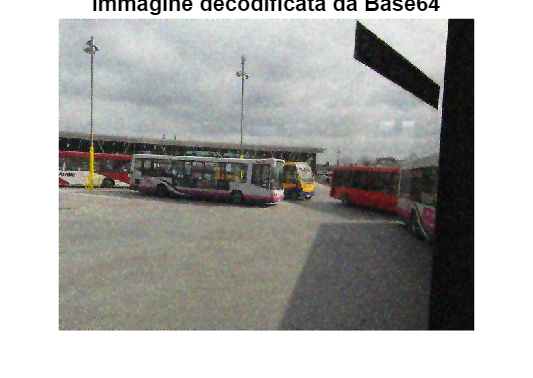

imgBytes = matlab.net.base64decode(i2);

% 2. Scrivi i byte in un file temporaneo
tempFile = [tempname, '.png'];
fid = fopen(tempFile, 'wb');
fwrite(fid, imgBytes, 'uint8');
fclose(fid);

% 3. Leggi l'immagine dal file e visualizzala
img = imread(tempFile);
imshow(img);
title('Immagine decodificata da Base64');


% (Opzionale) Cancella il file temporaneo
delete(tempFile);
niqe_noise

niqe_noise = 11.6849

niqe_denoised

niqe_denoised = 4.0214

Uniforme

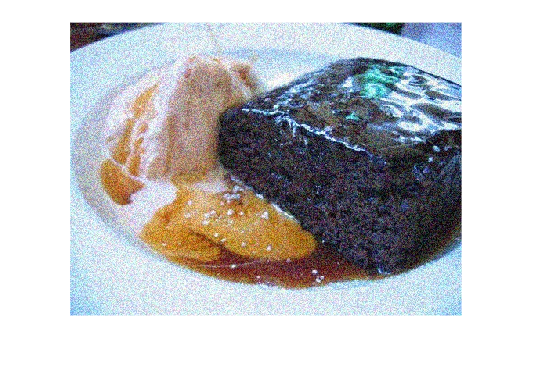

imshow(imageReader('uniform'));


i = imageReader('uniform');

[i2, niqe_noise, niqe_denoised] = noiseSelector(i, 'uniform')

i2 = 'iVBORw0KGgoAAAANSUhEUgAAAfQAAAF3CAIAAADckC6rAAAAB3RJTUUH6QcJCy4kCeZxbAAAIABJREFUeJwsumezZkd2nbldZh7zmutN3fIoA6DRaKMmKVGUQgpNTMT84/k2E0FFzAwpkc1ugCCARsMUyl5/X3POycy993xo/YgnYq1nLUxAAboALXLENniqcSc3BHubZrdpMuT1pgzDTJCwvKHd+i1tFjvY/dwczg+2cLvJ6/vHxzebcHF7UDLH4dVekgSIQhufLIUp+vn6Ni1mM4H99dU8dHe6yJUeHR1v19MP726X9x7kGH/5u18Bbn//3//HcnOy2J1/8B9v5PL0wf3NuLl5f566Q2ieX15v9mdGvpkvmSPdrddT8evNpNtg594gNI3Wze08LIAa2D3+MFycPAlFV8s6W61W13QX2i7Kzu3aCjb5+mpnljqf9ptm2c36xcnPHy5e/u7XqeGjrvv+m3882a8X5fpdG9TD8O1lLPLpp5+fW75oPM520h3/+MWPHz18fLx3sNfNXO348KM/ff1jK7tvz68OHz28WJ/3s822TI9/8Xe3q7XnK6BxPm9R5MWzX/xw/tOLv37h4/VfzY7rtLla6Pc/vPn14W/G282zj2cfrktKCckbsS+//O7gZO/B/b2vv1n3O4t31x8+//jw+rt3gUq/F7vFTFFe/Xw1Tni5vnv6+eMxb+A67+0eZofhZrp7dTtrlrUJFmXn0P/wL18+Pdsrm1WAnfd3V+2z07fvXqdV+bvPPv/2f/5hs95yv5g/OH5fbxfH/Wrz/jdnzzsdG2hXU83Uffv6fOf4lBR/+PbbT08frK+uOctHn++fCwp4D/Tdv7159OTkTz++efL43tffvwm82y96LcM43T356KhMVS7zXt+/ubta5+tuRuASy8nmYny4vzgfVnZfN5o3P+mLh8eLuSnSRcbbVXmwy8N6iG1cbW/7xez68mrzp7tf/ublP/3p209+8exPX3

niqe_noise = 12.7635

niqe_denoised = 3.9038

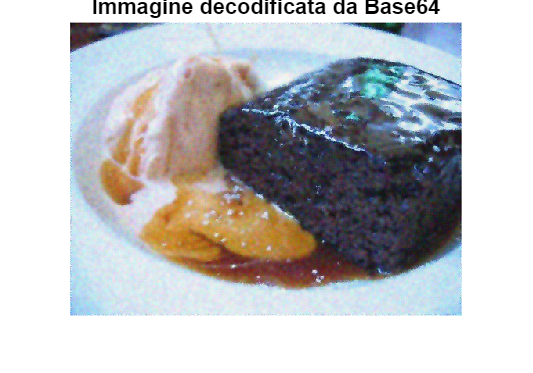

imgBytes = matlab.net.base64decode(i2);

% 2. Scrivi i byte in un file temporaneo
tempFile = [tempname, '.png'];
fid = fopen(tempFile, 'wb');
fwrite(fid, imgBytes, 'uint8');
fclose(fid);

% 3. Leggi l'immagine dal file e visualizzala
img = imread(tempFile);
imshow(img);
title('Immagine decodificata da Base64');


% (Opzionale) Cancella il file temporaneo
delete(tempFile);
niqe_noise

niqe_noise = 12.7635

niqe_denoised

niqe_denoised = 3.9038

Gaussiano

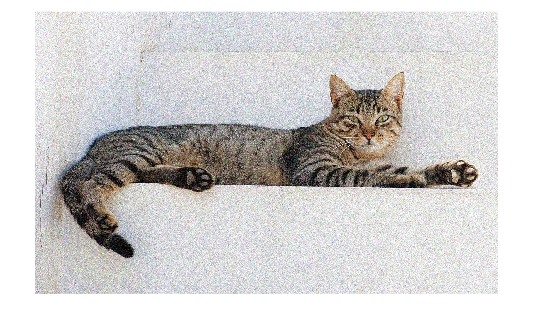

i2 = imageReader('cat_august_gaussian');
imshow(i2);

i = noiseSelector('cat_august_gaussian','gaussian');

Error using im2double
Expected input number 1, Image, to be one of these types:

double, logical, uint8, uint16, int16, single

Error in im2double (line 36)
validateattributes(img,{'double','logical','uint8','uint16','int16','single'},{}, ...

Error in gaussNoiseRemover (

imshow(i)

Sale & Pepe

imshow(imageReader('michele_sp'))


i = noiseSelector('michele_sp','sp');
imshow(i)

Periodico

imshow(imageReader('cat_august_periodicnoise'));

i = noiseSelector('cat_august_periodicnoise', 'periodic');
imshow(i)

Striping Orizzontale

imshow(imageReader('peppers_horizontal_stripes'));

i = noiseSelector('peppers_horizontal_stripes', 'hstriping');
imshow(i)

Striping Verticale

imshow(imageReader('peppers_vertical_stripes'));

i = noiseSelector('peppers_vertical_stripes', 'vstriping');
imshow(i)